**INIT**

close all; clear all;

**GLOBAL VARS**

alpha = 0.1;
entropyArea = 9;

**READ ORIGINAL IMAGE**

image = imread('../res/image.tif','tif');
[dimx,dimy] = size(image);
imageDouble   = double(image);

**READ IMAGE TO CHECK**

watImage = imread('../output/watImage.tif','tif');

**ATTACK IMAGE**

Iatt=watImage;

%attacks here
%Iatt = imsharpen(Iatt, 'Radius', 3, 'Amount', 2);
Iatt = imgaussfilt(Iatt,1);

**READ WATERMARK**

wSize = 1024;
w = open("../res/pufferfish.mat");
watermark = w.w;
flatWatermark = reshape(watermark, 1, wSize);

**FILTER ENTROPY**

[minEnt, entSize, entropyMatrix, entropySorted, entropyIndexes] = filterEntropy(image, entropyArea, dimx, dimy);

**DETECT WATERMARK**

newWat = zeros(1, wSize);
attWat = zeros(1, wSize);
for i = 1:wSize
    index = entropyIndexes(i);
    newPixel = watImage(index);
    attPixel = Iatt(index);
    originalPixel = image(index);
    entropy = entropySorted(i);
    strength = (entropy - minEnt)/entSize;
    if(newPixel == 255)
        newWat(i) = 1;
    else
        newWat(i) = (newPixel-originalPixel)/(strength * alpha * originalPixel);
    end
    if(attPixel == 255)
        attWat(i) = 1;
    else
        attWat(i) = (attPixel-originalPixel)/(strength * alpha * originalPixel);
    end
end

**SHOW RESULTS**

res = newWat == flatWatermark;
sum(res)

ans = 1024

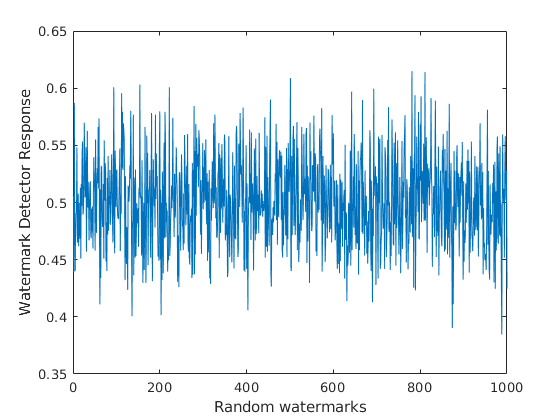



w_new=zeros(1000,1024);
for n = 1:499
    w_new(n,:) = round(rand(1,1024));
end
w_new(500,:) = flatWatermark;
for n = 501:1000
    w_new(n,:) = round(rand(1,1024));
end

sim=zeros(1,1000);
for n = 1:1000
    sim(n) = attWat.*w_new(n,:)/sqrt(attWat.*attWat);
end

x = 1:1000;
plot(x,sim); xlabel('Random watermarks'); ylabel('Watermark Detector Response');

wpsnr=WPSNR(uint8(watImage),uint8(Iatt))

wpsnr = 45.7563


sorted=sort(sim,'descend');

if(sim(500)>(sorted(2)*(1.1)))
    	fprintf('true\n');
else
    fprintf('false\n');
end

false


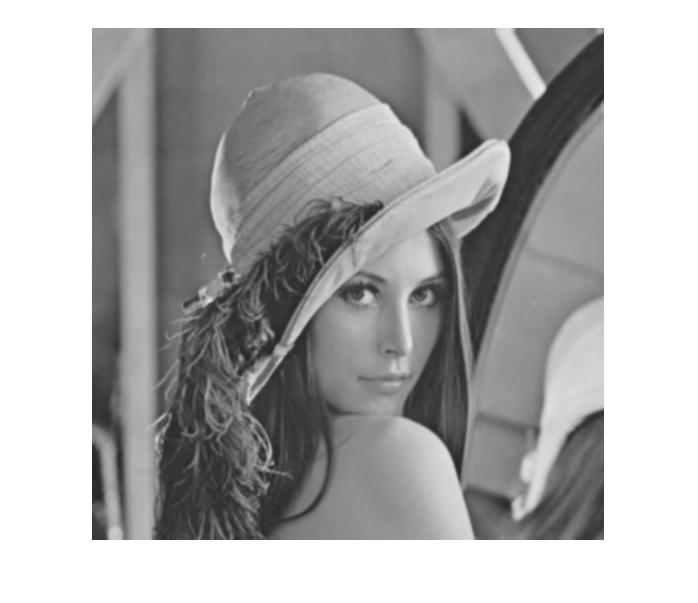

imshow(Iatt);